clear
clc

format long
TestDat = readtable('TEST3.csv');

time = table2array(TestDat(:,1));
dt = table2array(TestDat(:,2));
scanNum = table2array(TestDat(:,3));
x1 = table2array(TestDat(:,4));
y1 = table2array(TestDat(:,5));
z1 = table2array(TestDat(:,6));

x2 = table2array(TestDat(:,7));
y2 = table2array(TestDat(:,8));
z2 = table2array(TestDat(:,9));

gx1 = table2array(TestDat(:,10));
gy1 = table2array(TestDat(:,11));
gz1 = table2array(TestDat(:,12));


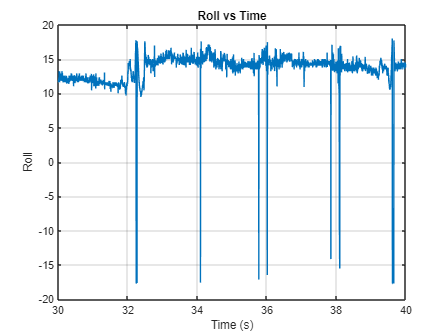


x_Buff = (x1);
y_Buff = (y1);
z_Buff = (z1);
roll = atan2(y_Buff , z_Buff) .* 5.73;
pitch = atan2((- x_Buff) , sqrt(y_Buff .* y_Buff + z_Buff .* z_Buff)) .* 5.73;

figure(55)
plot(time,roll)
xlim([30 40])
grid on
title('Roll vs Time')
xlabel('Time (s)')
ylabel('Roll')

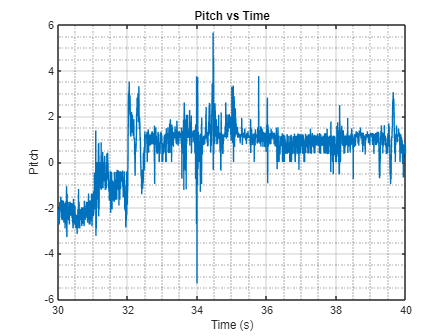


figure(56)
plot(time,pitch)
xlim([30 40])
grid on
grid minor
title('Pitch vs Time')
xlabel('Time (s)')
ylabel('Pitch')